# Least squares approximation with orthogonal polynomials

Consider the function $f:[-1,1]\rightarrow \mathbb{R}$, $f(x)=x+\sin2\pi x^2$.

Find the following least squares approximation with orthogonal polynomials

- continuous Legendre

- continuous Chebyshev #1

- discrete Chebyshev #1, with Chebyshev roots

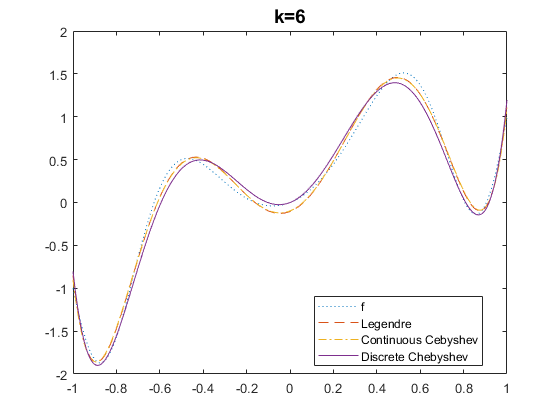

k=6;
fp=@ (x) x+sin(2*pi*x.^2);
x=linspace(-1,1,200);
y=fp(x);
yle=Legendreapprox(fp,x,k);
ycc=Chebyshevapprox(fp,x,k);
ycd=discrChebyshevapprox(fp,x,k);
plot(x,y,':', x,yle,'--', x,ycc,'-.',x,ycd,'-');
legend('f','Legendre', 'Continuous Cebyshev', 'Discrete Chebyshev',...
    'Location','best')
title(['k=',int2str(k)],'Fontsize',14);

disp('Legendre coeffs')

Legendre coeffs


cl=Legendrecoeffs(fp,k)

cl =     0.1717    1.0000   -1.3206    0.0000   -2.8534   -0.0000   21.7900


disp('Chebyshev #1 coeffs')

Chebyshev #1 coeffs


ccc=Chebyshevcoeffs(fp,k)

ccc =     0.0000    1.0000   -0.5692   -0.0000   -0.0000         0    0.6669


disp('discrete Chebyshev #1 coeffs')

discrete Chebyshev #1 coeffs


ccd=discrChebyshevcoeffs(fp,k)

ccd =    -0.0137    1.0000   -0.5692   -0.0000    0.1045    0.0000    0.6669
